Seleccione el tipo de movimiento:


1. Movimiento recto


2. Giro a la izquierda


3. Giro a la derecha


4. Vehículo detenido


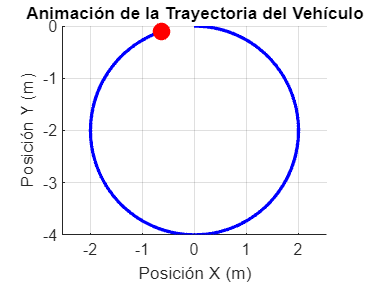

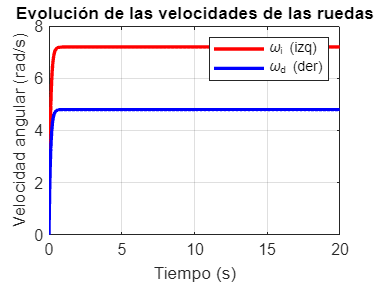

%% Limpieza del entorno
clc; clear; close all;


%% Parámetros del vehículo (valores iniciales)
R = 0.1;    % Radio de las ruedas (m)
K = 0.4;    % Mitad de la distancia entre ruedas (m)
tau = 0.12; % Constante de tiempo de los actuadores (s)
T = 0.025;  % Periodo de muestreo (s)
k_w = 1;    % Ganancia del sistema

% Entrada del usuario para parámetros básicos
Tsim = input('Ingrese el tiempo total de simulación (s): ');
vel_max = input('Ingrese la velocidad angular máxima de las ruedas (rad/s): ');

N = round(Tsim / T); % Número de pasos de simulación

%% Menú interactivo para seleccionar tipo de movimiento
disp('Seleccione el tipo de movimiento:');
disp('1. Movimiento recto');
disp('2. Giro a la izquierda');
disp('3. Giro a la derecha');
disp('4. Vehículo detenido');
opcion = input('Ingrese el número de la opción deseada: ');

% Asignar valores según la selección
switch opcion
    case 1  % Movimiento recto
        omega_id = vel_max;
        omega_dd = vel_max;
    case 2  % Giro a la izquierda
        omega_id = vel_max * 0.8;
        omega_dd = vel_max * 1.2;
    case 3  % Giro a la derecha
        omega_id = vel_max * 1.2;
        omega_dd = vel_max * 0.8;
    case 4  % Vehículo detenido
        omega_id = 0;
        omega_dd = 0;
    otherwise
        error('Opción inválida. Debe seleccionar un número entre 1 y 4.');
end

%% Inicialización de variables
x = zeros(1, N);  % Posición en X
y = zeros(1, N);  % Posición en Y
phi = zeros(1, N); % Orientación en radianes

omega_i = zeros(1, N); % Velocidad de la rueda izquierda
omega_d = zeros(1, N); % Velocidad de la rueda derecha

%% Bucle de simulación
figure;
hold on;
grid on;
xlabel('Posición X (m)');
ylabel('Posición Y (m)');
title('Animación de la Trayectoria del Vehículo');
axis equal;
h_trayectoria = plot(nan, nan, 'b', 'LineWidth', 2);
h_vehiculo = plot(nan, nan, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

for k = 1:N-1
    % DISCRETIZACIÓN del modelo de actuadores (Euler hacia adelante)
    omega_i(k+1) = omega_i(k) + T * (-omega_i(k)/tau + k_w * omega_id/tau);
    omega_d(k+1) = omega_d(k) + T * (-omega_d(k)/tau + k_w * omega_dd/tau);

    % DISCRETIZACIÓN de la cinemática diferencial
    v = (omega_d(k+1) + omega_i(k+1)) * R / 2;
    w = (omega_d(k+1) - omega_i(k+1)) * R / (2 * K);

    % Actualizar la orientación (discretización de phi)
    phi(k+1) = phi(k) + T * w;

    % Actualizar la posición (discretización de x e y)
    x(k+1) = x(k) + T * v * cos(phi(k));
    y(k+1) = y(k) + T * v * sin(phi(k));
    
    % Actualizar la animación en tiempo real
    set(h_trayectoria, 'XData', x(1:k+1), 'YData', y(1:k+1));
    set(h_vehiculo, 'XData', x(k+1), 'YData', y(k+1));
    pause(0.01); % Pausa para visualizar la animación
end

%% Gráficos adicionales: evolución de las velocidades
figure;
plot((0:N-1) * T, omega_i, 'r', 'LineWidth', 2); hold on;
plot((0:N-1) * T, omega_d, 'b', 'LineWidth', 2);
xlabel('Tiempo (s)');
ylabel('Velocidad angular (rad/s)');
title('Evolución de las velocidades de las ruedas');
legend('\omega_i (izq)', '\omega_d (der)');
grid on;
